## Ejercicio 9 del Boletín 3

Este problema resuelve la adaptación de la carga usando dos elementos circuitales reactivos $z_1 =jx_1$ y $z_2 =jx_2$ en configuración L. El objetivo es que la línea vea una carga normalizada $z=1$.

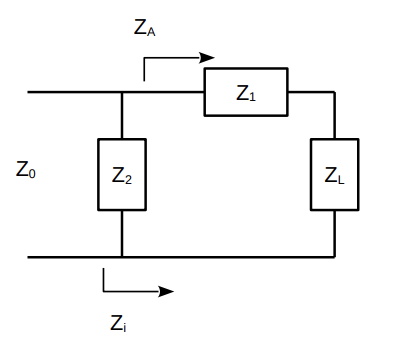

Como siempre, la clave la da el circuito. La impedancia que ve la línea de transmisión es la asociación de $z_2$ en paralelo con la suma $z_1 +z_L$. Esta suma debe ser la condición de acoplo, 1.


$$z_{\textrm{in}} =z_2 \|\left(z_1 +z_L \right)=1$$


Manipulamos un poco la expresión para que nos den cosas más faciles de buscar en la carta:

$1=\frac{1}{\frac{1}{jx_2 }+\frac{1}{jx_1 +z_L }}$;

$\frac{1}{jx_2 }+\frac{1}{jx_1 +z_L }=1$;

$\frac{1}{jx_1 +z_L }=1-\frac{1}{jx_2 }$;


$$jx_1 +z_L =$$

$$\frac{1}{1-\frac{1}{jx_2 }}$$


Cualquiera de las dos últimas expresiones nos vale: O bien comparamos la admitancia (el inverso) de la combinación en serie $jx_1 +z_L$ con la admitancia de la condición de acoplo 1 más cualquier valor imaginario, o bien comparamos la impedancia (el inverso) de la condición de acoplo 1 más cualquier valor imaginario con la impedancia en serie $jx_1 +z_L$. Preferimos usar la última ecuación. Buscamos la impedancia de la carga más la susceptancia 1 en serie.

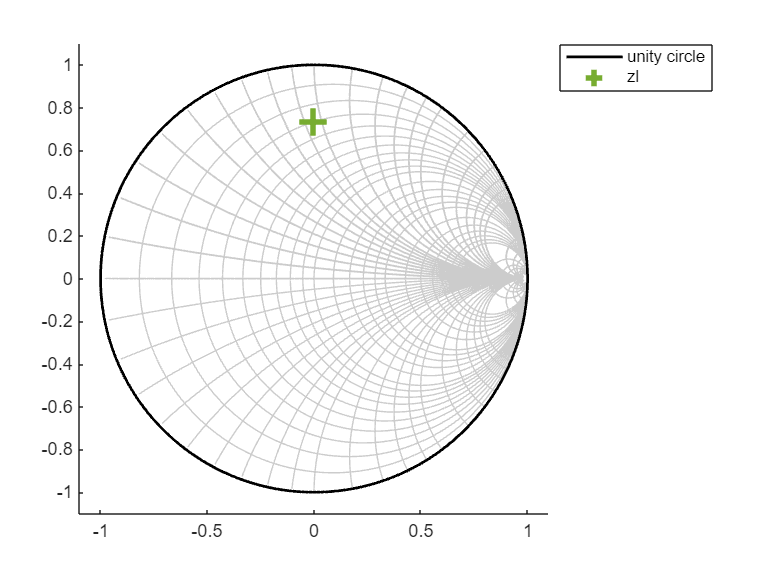

sm = Smithchart;
sm = sm.addz(0.3 + 1i*0.95, "zl");  % EDITABLE. Introducimos la impedancia de carga
sm.plotall("lines");

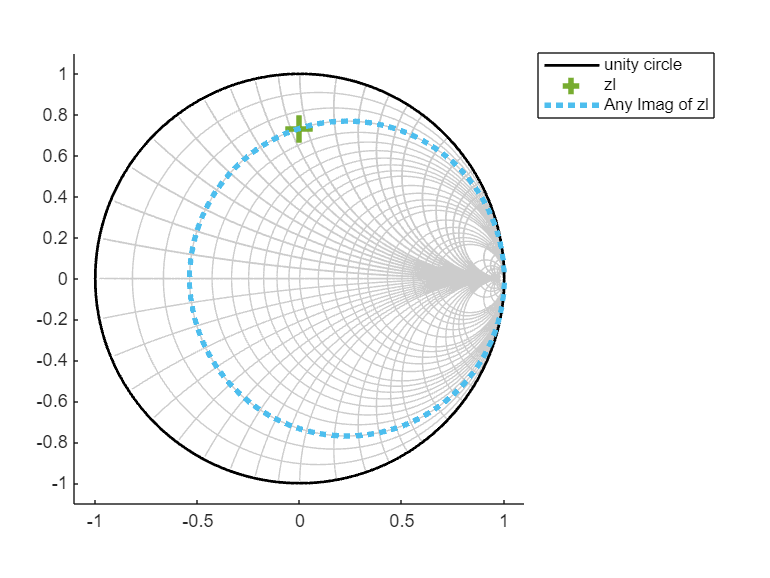

sm = sm.imagfree();  % Le añadimos cualquier valor imaginario
sm.plotall("lines");

El otro lado proviene de la condición de acoplo en admitancia 1 más cualquier valor imaginario.

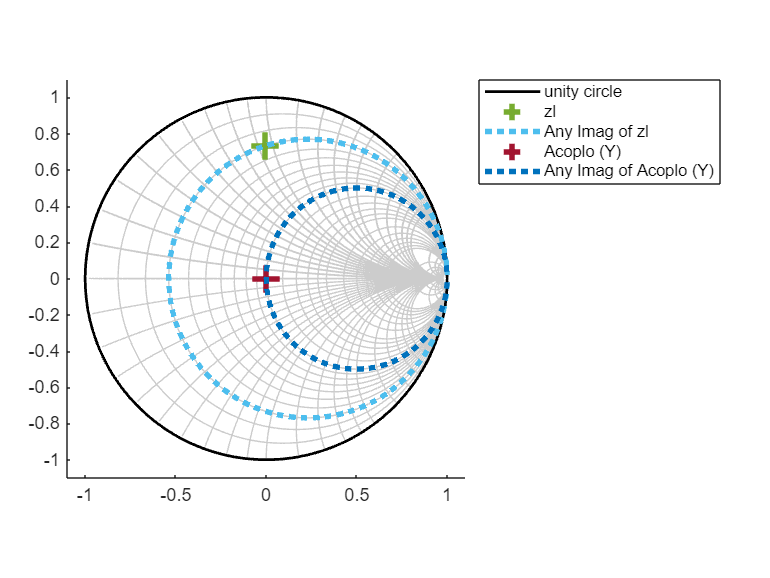

sm = sm.addz(1, "Acoplo (Y)");  % Cargamos la admitancia 1
sm = sm.imagfree();             % Le añadimos cualquier valor
                                % imaginario, que proviene de z2
sm.plotall("lines");

No podemos igualar admitancias con impedancias, por lo que una de ellas hace falta invertirla. Invertimos la admitancia del acoplo.

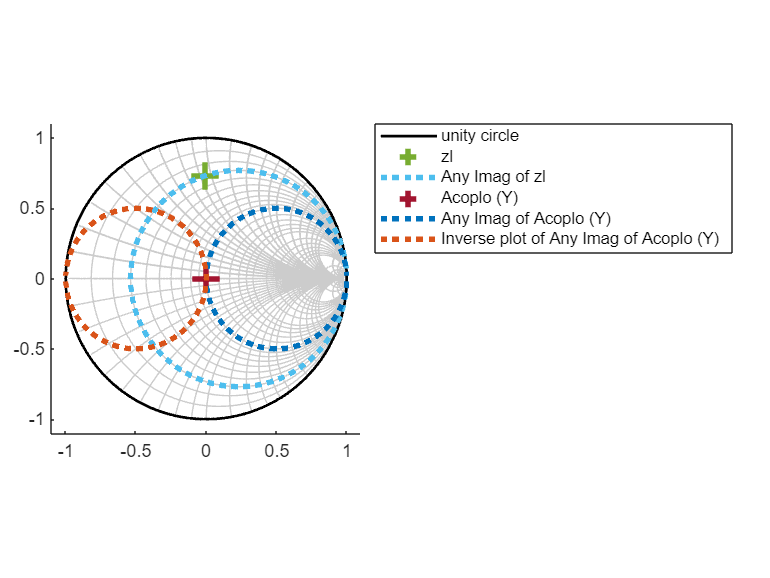

sm = sm.addadmit();  % Invertimos la curva de admitancia para
                     % hacerla de impedancia
sm.plotall("lines");

Así obtenemos dos puntos donde se cortan las curvas. Esos puntos son los que hay que usar en la ecuación para despejar finalmente $x_1$ y $x_2$. Supongamos que el punto que leemos en la carta es $z=r+j\;x$. Entonces despejamos $x_1$ de:


$$r+j\;x=jx_1 +z_L$$


Y despejamos $x_2$ de


$$r+j\;x=$$

$$\frac{1}{1-\frac{1}{jx_2 }}$$


Para este último paso, podemos volver a usar la carta de Smith para invertir $z=r+j\;x$, leer su valor $\frac{1}{r+j\;x}=g+j\;b$ en la carta, que estará sobre la curva de Acoplo (Y) e igualarlo a $1-\frac{1}{jx_2 }$, es decir:


$$1-\frac{1}{jx_2 }=g+j\;b$$


¿Que valores de impedancia de carga no se pueden acoplar con esta configuración?